## Cross-subject seizure detection model traning with DTF feature

clc, close, clear 
addpath(genpath("Analysis"))

% Load data path 
loadDataPath = fileparts(fileparts(pwd));
addpath(genpath(fullfile(loadDataPath, "Data")))

rng default
load Subjects.mat

subjectName = ["Dog_1", "Dog_2", "Dog_3", "Dog_4"];

% Adjust the "specifyIndex" for the choose of target subject
% i.e: specifyIndex = 1 -> Dog_1
specifyIndex = 1;

**Hyperparameter setting, (1) **`momentum`**, (2) **`alpha`**, (3) **`beta`**, followed the MNIST demonstration of following: "Domain-Adversarial Training of Neural Networks"**

- **cnn: (1) CNN: **`true`**, (2) DANN: **`false`

- **miniBatchSize: batch size, usually **

- **numEpochs: training process would end when finishing training last epoch **

- **momentum: hyperparameter of adjusting the speed of optimizer**

- **initialLearnRate: intial learning rate**

- **alpha: hyperparameter of adjusting the speed of optimizer**

- **beta: hyperparameter of adjusting the speed of optimizer**

% Traning_oprtions 
dannOpt = trainDannOptions(cnn = true, ...
                           miniBatchSize = 128, ...
                           numEpochs = 1, ...
                           momentum = 0.9, ...
                           initialLearnRate = 0.001, ...
                           alpha = 10,...
                           beta = 0.75)

dannOpt = struct with fields:
           trainType: 1
       miniBatchSize: 128
           numEpochs: 1
            momentum: 0.9000
    initialLearnRate: 1.0000e-03
               alpha: 10
                beta: 0.7500
      modelSelection: "CNN"




% Save options 
saveOpt = saveOptions(modelName = "dog2d", ...
                      performanceName = "loss_dog2d", ...
                      source_only = dannOpt.trainType)

saveOpt = struct with fields:
    modelName: "dog2d_cnn"
     PerfName: "loss_dog2d_cnn"


gpurng(0)

## **Train validation split **

% Split source/target 
leaveOneIndice = [1,2,3,4];
sourceSubject = subjectName(leaveOneIndice ~= specifyIndex);
targetSubject = subjectName(leaveOneIndice == specifyIndex);

% Save direction 
modelFolderDirection = sprintf("model/%s_2d/", dannOpt.modelSelection);
resultDirection = sprintf("result/%s_2d/", dannOpt.modelSelection);
aucDirection = sprintf("aucValidation/%s_2d/", dannOpt.modelSelection);
createFolder(modelFolderDirection); createFolder(resultDirection); createFolder(aucDirection);

**Train data**

% Load train data 
trainSourceIctal = cell(1, length(sourceSubject));
trainSourceInterictal = cell(1, length(sourceSubject));

parfor loadDataIter = 1:length(sourceSubject)
    data = load(sprintf("Seizure_detection_DTF_graph/%s_DTF_AIC_order", sourceSubject(loadDataIter)));
    
    ictal = data.ictal2;
    interictal = data.interictal2;

    % transpose
    ictal = cellfun(@(x) transpose(x{1}), ictal, 'UniformOutput', false);
    interictal = cellfun(@(x) transpose(x{1}), interictal, 'UniformOutput', false); 

    % cell to double 
    trainSourceIctal{loadDataIter} = sequenceTo4DArray(ictal);
    trainSourceInterictal{loadDataIter} = sequenceTo4DArray(interictal);
      
end
clearvars data

[normalizeTrainSourceData, ~, dogSz] = trainDataNormalize([trainSourceInterictal, trainSourceIctal]);

Data standardized



% normalized => Oversampling 
for i = 1:length(sourceSubject) 
    oversamplingIdx = oversampling(normalizeTrainSourceData{i+length(sourceSubject)}, normalizeTrainSourceData{i});
    data = normalizeTrainSourceData{i+length(sourceSubject)}; 
    normalizeTrainSourceData{i+length(sourceSubject)} = data(:,:,:,oversamplingIdx);
end

    "Number of ictal:"    "172"

    "Number of interictal:"    "1148"

    "Number of ictal:"    "480"

    "Number of interictal:"    "4760"

    "Number of ictal:"    "257"

    "Number of interictal:"    "2790"




trainSourceInterictal = cellConcatenate(normalizeTrainSourceData(1:length(sourceSubject)));
trainSourceIctal = cellConcatenate(normalizeTrainSourceData(length(sourceSubject)+1:end));

clearvars normalizeTrainSourceData

**Target data**

targetData = load(sprintf("Seizure_detection_DTF_graph/%s_DTF_AIC_order", targetSubject));

targetDataIctal = targetData.ictal2;
targetDataInterictal = targetData.interictal2;

% Index 
load(sprintf("Analysis/KaggleValidationIdx/%s_valIdx", targetSubject))

% transpose
targetDataIctal = cellfun(@(x) transpose(x{1}), targetDataIctal, 'UniformOutput', false);
targetDataInterictal = cellfun(@(x) transpose(x{1}), targetDataInterictal, 'UniformOutput', false);

trainTargetIctal = sequenceTo4DArray(targetDataIctal(tarIndexIctal~=1));
validationTargetIctal = sequenceTo4DArray(targetDataIctal(tarIndexIctal==1));

trainTargetInterictal = sequenceTo4DArray(targetDataInterictal(tarIndexInterctal~=1));
validationTargetInterictal = sequenceTo4DArray(targetDataInterictal(tarIndexInterctal==1));

% Normalize
if dannOpt.trainType == false % using target data to normalize
    [normalizeTrainTargetData, normalizeValTargetData, dogSzM] = trainDataNormalize([{trainTargetInterictal},{trainTargetIctal}], [{validationTargetInterictal},{validationTargetIctal}]);

else % using source data to normalize
    [normalizeTrainTargetData, ~, ~] = trainDataNormalize([{trainTargetInterictal},{trainTargetIctal}]);
    normalizeValTargetData = testDataNormalize([{validationTargetInterictal},{validationTargetIctal}], dogSz);
end

Data standardized


Data standardized




% Non-oversampling
trainTargetIctal = normalizeTrainTargetData{2};
trainTargetInterictal = normalizeTrainTargetData{1};

% Validation 
validationTargetIctal = normalizeValTargetData{2};
validationTargetInterictal = normalizeValTargetData{1};

clearvars normalizeTrainTargetData normalizeValTargetData
clearvars targetData targetDataIctal targetDataInterictal 

## CNN Structure 

#### Reference: 

- CNN model, "Seizure Prediction Using Directed Transfer  Function and Convolution Neural Network  on Intracranial EEG"

- Domain classifier of DANN model: 2 flatten layer and 2 ReLu layer with refer to domain classifier in "Domain-Adversarial Training of Neural Networks" MNIST structure

% Trainsfer learning, same deep layers with AlexNet, without batchnormalization 
[h,w, ~,~] = size(trainTargetIctal);

FeatureExtractor = [ ...
        % Input image
        imageInputLayer([h w 1],'Normalization','none')   % Custom training loop normalize data at training batches
        convolution2dLayer(3, 8, 'Stride',1)
        reluLayer

        maxPooling2dLayer(2, 'Stride', 2)

        % 2nd 
        convolution2dLayer(5, 16,'Stride',[1,3])
        reluLayer

        maxPooling2dLayer(2, 'Stride', 2)

        convolution2dLayer(3, 32,'Stride',[1,3])
        reluLayer
        ];

LabelPredictor = [ ...
        % P1
        fullyConnectedLayer(256, Name="label_fc")
        dropoutLayer(0.5)

        % P2
        fullyConnectedLayer(128)
        dropoutLayer(0.5)
        
        % P3
        fullyConnectedLayer(2)
        softmaxLayer(Name="label_output")];

DomainClassifier = [...
        % FC layer 
        fullyConnectedLayer(256, Name="domain_fc")
        reluLayer

        % FC layer 
        fullyConnectedLayer(128)
        reluLayer

        % FC
        fullyConnectedLayer(1)
        sigmoidLayer(Name="domain_output")];

## Training process, without suffle 

% IterNum, minimum of the mnist/mnist_m
xTrain = dlarray(cat(4, trainSourceInterictal, trainSourceIctal), "SSCB");
xTargetTrain = dlarray(cat(4, trainTargetInterictal, trainTargetIctal), "SSCB");

targetOversamplingIndex = oversampling(xTargetTrain, xTrain);

    "Number of ictal:"    "477"

    "Number of interictal:"    "17396"



xTargetTrain = xTargetTrain(:,:,:,targetOversamplingIndex);

yTrain = cat(1, zeros(length(trainSourceInterictal), 1), ones(length(trainSourceIctal), 1));
yTrain = onehotencode(yTrain', 1, 'ClassNames', 0:1);
yTrain = dlarray(yTrain,"CB");

% Validation data 
xTargetValidation = dlarray(cat(4, validationTargetInterictal, validationTargetIctal), "SSCB");
yTargetValidation = cat(1, zeros(size(validationTargetInterictal,4), 1), ones(size(validationTargetIctal,4), 1));
yCellTargetValidation = onehotencode(yTargetValidation', 1, 'ClassNames', 0:1);  % OneHotEncode input 
yTargetValidation = dlarray(yTargetValidation,"CB");
yCellTargetValidation = dlarray(yCellTargetValidation,"CB");

% 
yTargetValidation = extractdata(yTargetValidation);
clearvars trainTargetInterictal trainSourceInterictal trainSourceIctal trainTargetIctal validationTargetInterictal validationTargetIctal

### Constructing network using function "dlnetwork"

dannNet = dlnetwork(FeatureExtractor);

% First branch 
dannNet = addLayers(dannNet, LabelPredictor);
dannNet = connectLayers(dannNet,"relu_3","label_fc");

% Second branch 
if dannOpt.trainType == false
    GRL = GradientReversalLayer;
    dannNet = addLayers(dannNet, [GRL; DomainClassifier]);
    dannNet = connectLayers(dannNet,"relu_3","GRL");
end

% The model weight would be freezed when constructing net using "addLayer",
% so "initialize" are here to initialize model weight
dannNet = initialize(dannNet);

% Calculate number of training loop iteration
numIterations= floor(length(yTrain) / dannOpt.miniBatchSize);

% if canUseGPU
%     XTrain = gpuArray(XTrain);
%     xTargetTrain = gpuArray(xTargetTrain);
% end

#### **Training per epoch  // domain classifier **close all

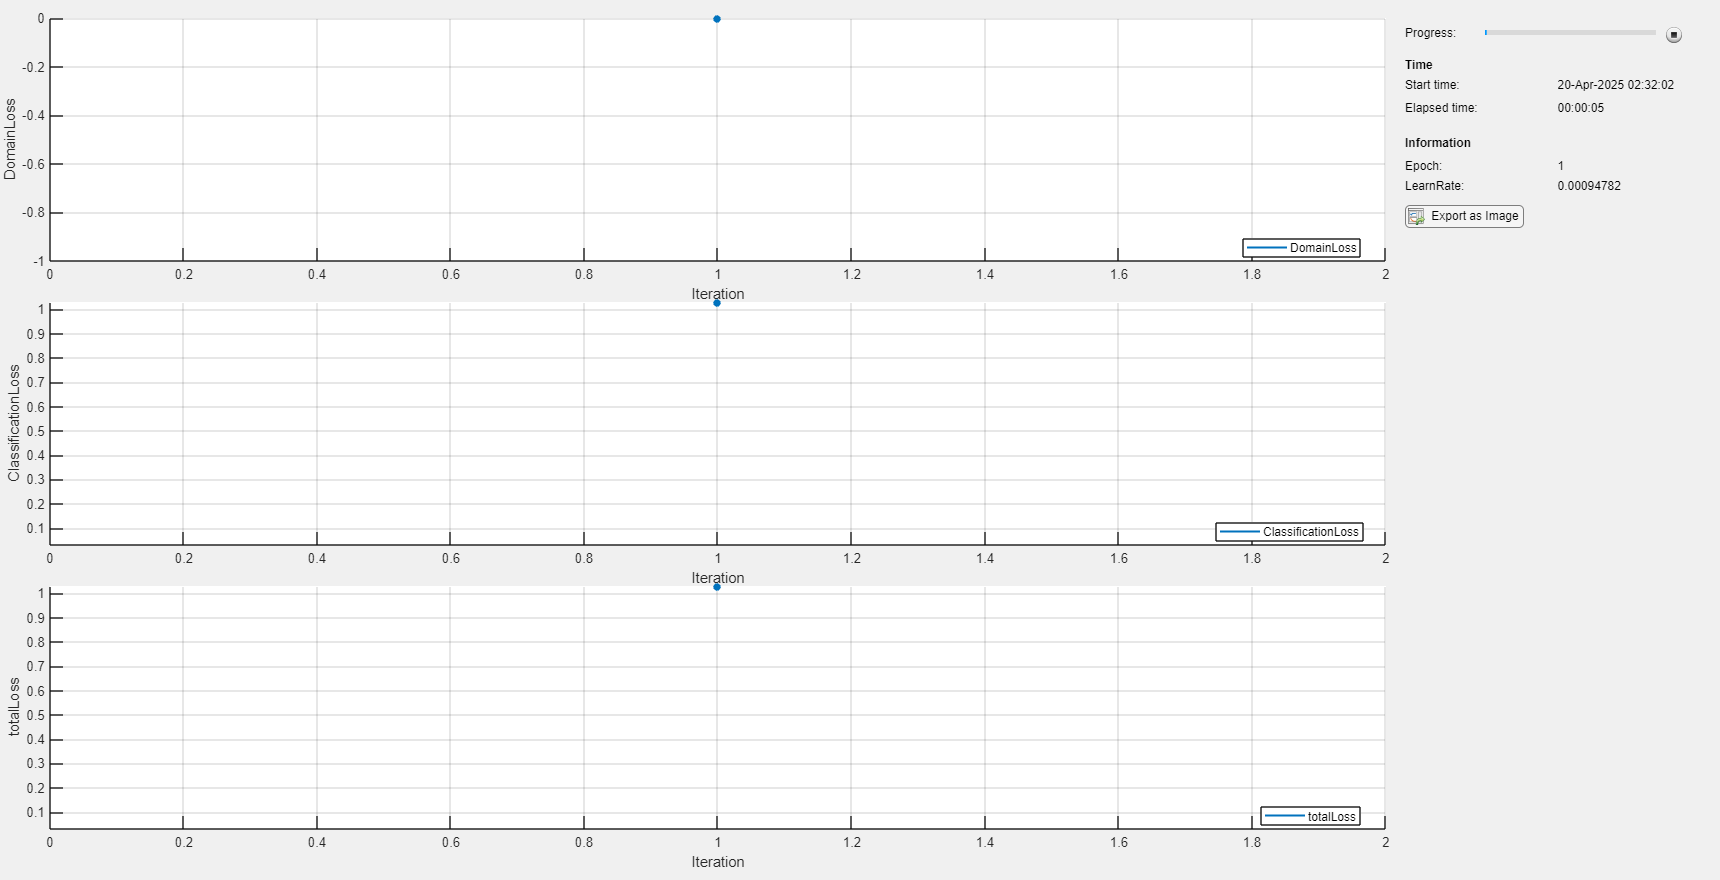

epoch = 0;
save_size = [dannOpt.numEpochs, numIterations];

% Loss 
totalLoss_Save = zeros(save_size);
domainLoss_Save = zeros(save_size);
sourceLoss_Save = zeros(save_size);
learningRate_Save = zeros(save_size);

% AUC
auc = cell(dannOpt.numEpochs, 4);

% loss 
validationLoss = zeros(1, dannOpt.numEpochs);
trainingLoss = zeros(1, dannOpt.numEpochs);

% SGDM
velocityF = [];
velocityD = [];

%
TotalIter = 0;

% Training GUI
monitor = trainingProgressMonitor(...
        Metrics= ["DomainLoss", "ClassificationLoss", "totalLoss"], ...
        Info=["Epoch" "LearnRate"], ...
        XLabel="Iteration");

while epoch < dannOpt.numEpochs && ~monitor.Stop

    % Parameter reset 
    epoch = epoch + 1;
    iter = 0;

    % Equals to matfunction(trainingOptions): Shuffle every-epoch
    [xTrain, yTrain] = shuffle(xTrain, yTrain);

    if dannOpt.trainType == false
        [xTargetTrain,~] = shuffle(xTargetTrain);
    end
    
    sourceIndex = 1:dannOpt.miniBatchSize;
    targetIndex = 1:dannOpt.miniBatchSize;

    % Training iteration start 
    while iter < numIterations && ~monitor.Stop
        
        iter = iter + 1;
        TotalIter = TotalIter + 1;

        % Read mini-batch data
        [trainBatch, trainSourceLabel, domainTrainData] = batch(xTrain, xTargetTrain, yTrain, sourceIndex, targetIndex);
        
        % Domain adaptation parameter: lambda 
        p = (iter + (epoch-1)* numIterations)/ (dannOpt.numEpochs* numIterations);

#### sDANN: Calculate two shallow NN loss 

        % Determine learning rate for time-based decay learning rate schedule.
        learnRate = dannOpt.initialLearnRate/((1 + dannOpt.alpha*p)^dannOpt.beta);

        lambda_p = 2./(1 + exp(-10* p))-1;
        
        % Training, fLoss: feature extractor, domain classifier.
        [fLoss,fGradient,fState] = dlfeval(@modelLoss,dannNet,trainBatch,trainSourceLabel,"normal",dannOpt.miniBatchSize);
        if dannOpt.trainType == false

            [dLoss,dGradient,dState] = dlfeval(@modelLoss,dannNet,trainBatch,domainTrainData,"adversarial");
            
            % multiply gradients of domain classifier with regularization       
            tmpGradient = cellfun(@(x) x.*lambda_p, dGradient.Value, 'UniformOutput', false);
            dGradient.Value = tmpGradient;
        else
            dLoss = 0; dGradient = 0;
        end
        
         % Comibination two branches
        totalLoss = dLoss + fLoss;

#### Reload learning rate, and domain classifier parameter /lambda

        % Update the network parameters using the SGDM optimizer.
        [dannNet, velocityF] = sgdmupdate(dannNet, fGradient, velocityF, learnRate, dannOpt.momentum);  
        if dannOpt.trainType == false 
            [dannNet, velocityD] = sgdmupdate(dannNet, dGradient, velocityD, learnRate, dannOpt.momentum);
        end

        % Update the training progress using monitor
        recordMetrics(monitor, TotalIter, DomainLoss=dLoss, ClassificationLoss = fLoss, totalLoss = totalLoss);
        updateInfo(monitor, Epoch=epoch, LearnRate = learnRate);
        monitor.Progress = 100* iter/numIterations;
        
        % Save training loss
        domainLoss_Save(epoch,iter) = dLoss;
        sourceLoss_Save(epoch,iter) = fLoss;
        totalLoss_Save(epoch,iter) = totalLoss;
        learningRate_Save(epoch,iter) = learnRate;
        
        sourceIndex = sourceIndex + dannOpt.miniBatchSize;
        targetIndex = targetIndex + dannOpt.miniBatchSize;

        clear fGradient dGradient   % zero_grad()
        clear trainSourceLabel domainTrainData trainBatch  
    end

####  Validation performance calculation 

    yValidationPrediction = predict(dannNet, xTargetValidation);

    [~, ValidationIndex] = max(yValidationPrediction,[],1);
    ValidationIndex = ValidationIndex(:);
    ValidationIndex = ValidationIndex -1; % 0,1 to 1,2 for classification 

    % Loss save 
    validationLoss(1,epoch) = crossentropy(yValidationPrediction, yCellTargetValidation);
    trainingLoss(1,epoch) = fLoss;

**  AUC**

    yValidationPrediction_ictal = extractdata(yValidationPrediction);
    [X,Y,T,AUC] = perfcurve(yTargetValidation,yValidationPrediction_ictal(2,:)',1);
    auc(epoch,:)={epoch,AUC,X,Y};

    disp(fprintf("epoch %d: train_F_loss: %04f, train_D_loss: %04f, AUC: %04f", epoch, sourceLoss_Save(epoch, end), domainLoss_Save(epoch, end), AUC))
    clear ValidationIndex
end

Save options

save(fullfile(modelFolderDirection, sprintf("%s_%d_%s.mat",saveOpt.PerfName, dannOpt.numEpochs, targetSubject)), "sourceLoss_Save", "domainLoss_Save", "totalLoss_Save", "learningRate_Save", "trainingLoss", "validationLoss");
save(fullfile(aucDirection, sprintf("%s_%d_%s.mat", saveOpt.PerfName, dannOpt.numEpochs, targetSubject)), "auc");
save(fullfile(resultDirection, sprintf("%s_%d_%s", saveOpt.modelName, dannOpt.numEpochs, targetSubject)), "dannNet");
finalAuc = AUC;

#### Plot setting 

% Plot section
close all
figure
startPlotEpoch = 1;  % Training epoch start with 1 
interval = 10;       % Ticks interval 

tickslabel = 0:interval:epoch;   % From 0 to end of the training epoch 
if mod(epoch, 10) ~= 0
    tickslabel = [tickslabel, epoch];
end
tickslabel(1) = 1;               % Replace first tick with start of the epoch 

**Plot**

subplot(3,1,1)
plot(startPlotEpoch:epoch, sourceLoss_Save(startPlotEpoch:epoch, end), "LineWidth",1)
xlim([startPlotEpoch, epoch])
xlabel("Epochs")
ylabel("Cross entropy loss")
title("Training loss of label predictor")
xticks(tickslabel)

subplot(3,1,2)
plot(startPlotEpoch:epoch, domainLoss_Save(startPlotEpoch:epoch, end), "LineWidth",1)
xlim([startPlotEpoch, epoch])
xlabel("Epochs")
ylabel("Cross entropy loss")
title("Training loss of domain classifier")
xticks(tickslabel)

subplot(3,1,3)
plot(startPlotEpoch:epoch, totalLoss_Save(startPlotEpoch:epoch, end), "LineWidth",1)
xlim([startPlotEpoch,epoch])
xlabel("Epochs")

ylabel("Summed loss")
title("Training loss of DANN")
xticks(tickslabel)

close all
figure
plot(startPlotEpoch:size(sourceLoss_Save, 1), sourceLoss_Save(startPlotEpoch:end, end), "LineWidth",1.5)
xlim([startPlotEpoch, epoch])
xlabel("Epochs", "FontSize", 12)
ylabel("Cross entropy loss", "FontSize", 12)
title("Training loss of label predictor", "FontSize", 14)
xticks(tickslabel)

close all
figure
plot(startPlotEpoch:size(domainLoss_Save, 1), domainLoss_Save(startPlotEpoch:end, end), "LineWidth",1.5)
xlim([startPlotEpoch, epoch])
xlabel("Epochs","FontSize", 12)
ylabel("Cross entropy loss","FontSize", 12)
title("Training loss of domain classifier", "FontSize", 14)
xticks(tickslabel)

close all
figure
plot(1:epoch, validationLoss(1:epoch), 'LineWidth',1.5)
xlim([1, epoch])
title("Validation loss", "FontSize",14)
xlabel("Epochs","FontSize", 12)
ylabel("Cross entropy loss","FontSize", 12)
xticks(tickslabel)

% ROC curve 
close all 
figure
plot(auc{epoch,3}, auc{epoch,4},"Linewidth",1.5)
if dannOpt.trainType == false
   titleName = sprintf("ROC curve of 2D-DANN to the %s", strrep(targetSubject, "_", " "));
else 
   titleName = sprintf("ROC curve of 2D-CNN to the %s", strrep(targetSubject, "_", " "));
end
hold on 
plot(linspace(0,1,length(auc{epoch,3})),linspace(0,1,length(auc{epoch,3})), "r--", "LineWidth",1.5)
hold off 
title(titleName)
xlabel("False positive rate")
ylabel("True positive rate")

#### Get final result with trained model, run first section and this section.

auc_plot = cellfun(@(x) x(1), auc(1:epoch,2), "UniformOutput",true);

close all 
figure
plot(1:epoch, auc_plot, "LineWidth",1.5)
title(sprintf("Validation AUC of %s", replace(targetSubject, "_", " ")), "FontSize",16)
xlim([1,length(auc_plot)])
xticks(tickslabel)
xlabel("Epochs", "FontSize", 12)
ylabel("AUC", "FontSize", 12)

function [loss, gradients, state] = modelLoss(net, X, T, mode,miniBatchSize)
% ------------------------------------------- %
% Calculate cross-entropy loss, backpropagation gradients, and renew values.
% Label predictior on source domain used.
% Define variables: 
%  net           -- CNN model 
%  X             -- minibatch data generate by batch function 
%  T             -- minibatch labels 
%  mode          -- Specify (1) "normal" as CNN, (2) "adversarial" as DANN
%  miniBatchSize -- number of minibatch samples
%  loss          -- minibatch cross-entropy loss 
%  gradients     -- gradients calculated by backpropagation 
%  state         -- renew state, calculated with gradients and model weights
% 
% ------------------------------------------- % 
% Label predictior examples:
%  net = dannNet; miniBatchSize = 128;
%  X = xTrain(:,:,:,1:miniBatchSize); T = yTrain(1:miniBatchSize);
%  [loss, gradients, state] = modelLoss(net, X, T, miniBatchSize, "normal");
% ------------------------------------------- % 
%   Date          Programmer     Description of change
%   ====          ==========     =====================
% 09/04/2025    ZhengChun Chen   Original code
% ------------------------------------------- %
switch mode 
    case "normal"       % Forward net branch 1

        [Y,state] = forward(net,X(:,:,:,1:miniBatchSize));
        loss =  crossentropy(Y,T);
 
    case "adversarial"  % Forward net branch 2 

        [~,Y,state] = forward(net,X);
        loss = crossentropy(Y,T,'ClassificationMode','multilabel');
end

% Calculate gradient with net.Learnables: model weights
gradients = dlgradient(loss,net.Learnables);
end

function [XTrain, XValidation, trainInfomation] = trainDataNormalize(xTrain, xValidation)
% ------------------------------------------- %
% z-score dataset using custom function "NormImgInfo"
% Define variables: 
%   xTrain                      -- source train data 
%   xValidation                 -- source validation data 
%   trainInfomation             -- variance, standard deviation, mean over dataset 
% examples:
% XTr = xTrain; [xTrain, ~, TrainInfo] = trainDataNormalize(XTr);
%   Date          Programmer     Description of change
%   ====          ==========     =====================
% 09/04/2024    ZhengChun Chen   Original code
% ------------------------------------------- %
    disp("Data standardized")
    wholeData = cellConcatenate(xTrain);

    % concatenate cells 
    trainInfomation = NormImgInfo(wholeData);
    channelsNumber = 1;
    XTrain = cell(size(xTrain));

    switch nargin 
        case 1
            for cellNumber = 1:length(xTrain)
            for i =1:channelsNumber
                XTrain{cellNumber}(:,:,i,:) = (xTrain{cellNumber}(:,:,i,:) - trainInfomation.mean(i))./trainInfomation.std(i);
            end
            end
            XValidation = [];
        case 2
            XValidation = cell(size(xValidation));
            for cellNumber = 1:length(xTrain)
            for i =1:channelsNumber
                XTrain{cellNumber}(:,:,i,:) = (xTrain{cellNumber}(:,:,i,:) - trainInfomation.mean(i))./trainInfomation.std(i);
                XValidation{cellNumber}(:,:,i,:) = (xValidation{cellNumber}(:,:,i,:) - trainInfomation.mean(i))./trainInfomation.std(i);
            end
            end
    end
    
end
function XTest = testDataNormalize(xTest, Info)
% ------------------------------------------- %
% z-score dataset using custom function "NormImgInfo", info of source data 
% Define variables: 
%   xTest           -- target train data 
%   information     -- struct, info of source data (std, var, mean)
%   XTest           -- normalized target test data 
% examples:
% [xTrain, ~, TrainInfo] = testDataNormalize(xTest, Info);
%   Date          Programmer     Description of change
%   ====          ==========     =====================
%  09/04/2024   ZhengChun Chen   Original code
% ------------------------------------------- %
    disp("Data standardized")
    channelsNumber = 1;
    XTest = cell(size(xTest));
    for cellNumber = 1:length(xTest)
        for i =1:channelsNumber
            XTest{cellNumber}(:,:,i,:) = (xTest{cellNumber}(:,:,i,:) - Info.mean(i))./Info.std(i);
        end
    end
end

function [xTrain, ySource, domainLabel] = batch(sourceTrainData, targetTrainData, sourceTrainLabel, sourceIndex, targetIndex)
% ------------------------------------------- %
% Generate minibatch samples 
% Define variables: 
%   sourceTrainData     -- training data of source domain 
%   targetTrainData     -- training data of target domain 
%   sourceTrainLabel    -- training label of source domain 
%   sourceIndex         -- minibatch index of source data 
%   targetIndex         -- minibacth index of target data 
%   xTrain              -- minibatch data with source and target data
%   ySource             -- minibatch source data labels
%   domainLabel         -- minibatch virtual source and target labels,
%
% examples:
% idx = 1:128; [xTrain, ySource, domainLabel] = batch(xTrain, yTrain, xTargetTrain, idx, idx);
%   Date          Programmer     Description of change
%   ====          ==========     =====================
%  2/12/2024    ZhengChun Chen   Original code
% ------------------------------------------- %

xSource = sourceTrainData(:,:,:,sourceIndex);
ySource = sourceTrainLabel(:,sourceIndex);
xTarget = targetTrainData(:,:,:,targetIndex);
xTrain = cat(4, xSource, xTarget);

% Domain label
domainLabel = zeros(length(sourceIndex)+length(targetIndex),1);
domainLabel(1:length(sourceIndex)) = 1;  % Source : 1
domainLabel(length(sourceIndex)+1:end) = 0;  % Target : 0

% One-hot encode for Binary Cross Entropy(BCE), specify as "CB" dlarrays
domainLabel = dlarray(domainLabel', 'CB');
end

function [x, y] = shuffle(x,y)
% ------------------------------------------- %
% shuffle images using one time "randperm" function in "4D-array" datastructure
% ""Same random seed setting will generate same suffle index""
% 
% Define variables: 
%   x  -- Data 
%   y  -- Label
% examples:
% x = rand(5,5,1,10); y = rand(1,5); [x, y] = shuffle(x, y');
%   Date          Programmer     Description of change
%   ====          ==========     =====================
%  2/12/2024    ZhengChun Chen   Original code
% ------------------------------------------- %
shuffleIndex = randperm(length(x));

x = x(:, :, :, shuffleIndex);

if nargin < 2
y = 0;
else
y = y(:, shuffleIndex);
end
end

function outputData = sequenceTo4DArray(data)
% ------------------------------------------- %
% Convert saved DTF feature from cell format to 4D-Array
% 
% Define variables: 
%   data        -- Data in cell format 
%   outputData  -- Data in 4D-Array
% examples:
% outputData = sequenceTo4DArray(data);
%   Date          Programmer     Description of change
%   ====          ==========     =====================
%  09/04/2024   ZhengChun Chen   Original code
% ------------------------------------------- %
inputSize = size(data{1});
outputData = zeros([inputSize, 1, length(data)]); 

for len = 1:length(data)
    outputData(:,:,1,len) = data{len};
end
end
function outputIdx = oversampling(data1, data2)
% ------------------------------------------- %
% Oversampling the minority till the size is equal to the priority
% by generating the oversampling index 
% 
% Define variables: 
%   data1/data2   -- Ictal data or interictal data, no specific orders(data: 4D-Array)       
%   outputIndex   -- Oversampling index of the minority
% examples:
%   data1 = ictal; data2 = interictal; outputIndex = oversampling(data1, data2)
%   Date          Programmer     Description of change
%   ====          ==========     =====================
%  09/04/2024   ZhengChun Chen   Original code
% ------------------------------------------- %

num_1=size(data1,4);
num_2=size(data2,4);

lessNum = min(num_1, num_2);
moreNum = max(num_1, num_2);

disp(["Number of ictal:", lessNum]);
disp(["Number of interictal:", moreNum]);

num_aug = moreNum - lessNum;
oversamplingIdx = randsample(1:lessNum, num_aug, true);
outputIdx = [(1:lessNum)'; oversamplingIdx'];
end
function createFolder(path)
    if ~exist(path, "dir")
        mkdir(path)
    end
end